## Signal intensity VS Flip angle :

GM_T1_3T = 1433.2

GM_T1_3T = 1.4332e+03

WM_T1_3T = 866.9

WM_T1_3T = 866.9000


GM_T2_3T = 109.4

GM_T2_3T = 109.4000

WM_T2_3T = 112/3

WM_T2_3T = 37.3333


GM_T2_Star = 88.4

GM_T2_Star = 88.4000

WM_T2_Star = 66.2

WM_T2_Star = 66.2000

Alpha = [5:33]

Alpha =      5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33


TE = 25

TE = 25

TR_SWI = 38

TR_SWI = 38


Signal_WM = ((sind(Alpha).* (1-exp(-TR_SWI ./ WM_T1_3T))) .* exp(-TE ./ WM_T2_Star)) ./ (1 - cosd(Alpha) .* exp(-TR_SWI/WM_T1_3T))

Signal_WM =     0.0551    0.0638    0.0716    0.0784    0.0841    0.0889    0.0928    0.0958    0.0981    0.0997    0.1008    0.1013    0.1015    0.1012    0.1007    0.0999    0.0990    0.0978    0.0965    0.0952    0.0937    0.0922    0.0907    0.0891    0.0875    0.0859    0.0843    0.0827    0.0812


Signal_GM = ((sind(Alpha).* (1-exp(-TR_SWI ./ GM_T1_3T))) .* exp(-TE ./ GM_T2_Star)) ./ (1 - cosd(Alpha) .* exp(-TR_SWI/GM_T1_3T))

Signal_GM =     0.0575    0.0654    0.0719    0.0770    0.0809    0.0836    0.0854    0.0864    0.0868    0.0866    0.0860    0.0851    0.0839    0.0825    0.0810    0.0794    0.0778    0.0761    0.0744    0.0727    0.0710    0.0693    0.0677    0.0661    0.0645    0.0629    0.0615    0.0600    0.0586



hold on
plot(Alpha, Signal_WM, "DisplayName","WM")
plot(Alpha, Signal_GM, "DisplayName","GM")
xlabel("Angle de bascule en degré")
ylabel("Signal")
hold off
legend("Location", "best")
lgd.NumColumns = 2

lgd = struct with fields:
    NumColumns: 2


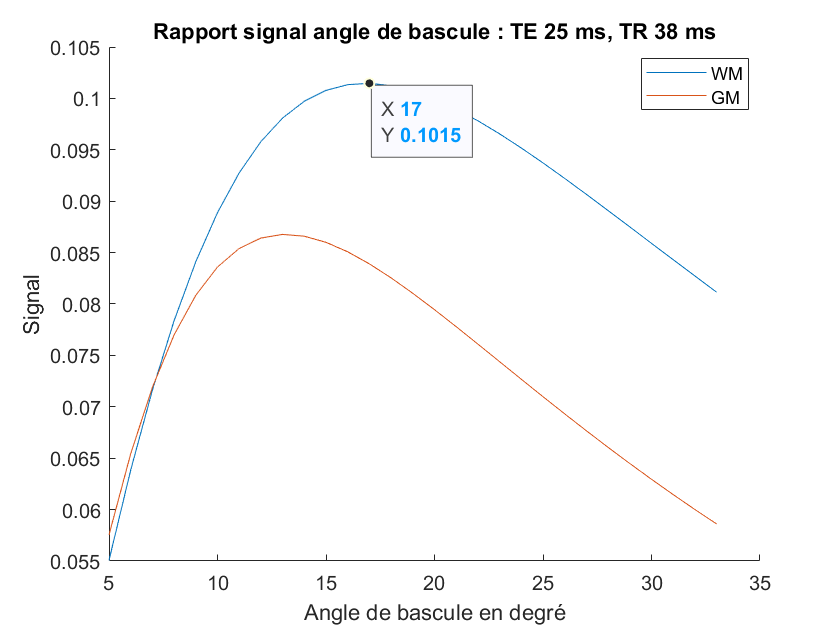

title("Rapport signal angle de bascule : TE 25 ms, TR 38 ms")